# 07 | Offline gamma-state identification 

INPUT: ONE continuous 60-s preprocessed segment; fs is read from the MAT. OUTPUT: coefficients, thresholds, candidate/confirmed states and settings. TOOLBOXES: Signal Processing and Wavelet. Steps follow the original code: resample -> window -> WP coefficients -> threshold -> candidate state -> temporal confirmation -> save/inspect. This is a MATLAB teaching implementation, not a replacement for recorded Qt states. Boundary/startup conventions can differ from the online implementation.

## 1. Paths and fixed parameters

codeDir = 'H:\closed-loop data paper\0 group analysis\GATE-Pain\code\offline data analysis_v2_20260923';
addpath(fullfile(codeDir,'functions'));
outDir=gate_output_dir(codeDir,'07_states');
inputFile=fullfile(codeDir,'example_inputs','Rat07_130Hz_OL_Pre_seg010.mat');
stateInputFs=320; windowSamples=64; updateSamples=8;
waveletBasis='sym2'; targetNode=[2 1];
initializationSeconds=3;
coefficientFraction=0.5;
extraGamma1=1; extraGamma0=3;      % Additional candidates AFTER first detection.
referenceMode='confirmed_gamma0'; % Method description: update in gamma0, hold in gamma1.
% Some original OFFLINE scripts use 'rolling' (update after every valid step).
% That option is available explicitly below. It is not silently interchangeable
% with the online state-gated reference. Keep this choice in any exported result.
previewSeconds=[10 15];

## 2. Resample one continuous record 

[signal,originalFs]=gate_load_lfp(inputFile);
[upFactor,downFactor]=rat(stateInputFs/originalFs,1e-12);
signal=resample(signal,upFactor,downFactor);
fs=stateInputFs;
updateSeconds=updateSamples/fs; state_fs=1/updateSeconds;
nUpdates=floor(numel(signal)/updateSamples);
nInit=round(initializationSeconds/updateSeconds);
nCoefficientsWindow=ceil(windowSamples/2^targetNode(1));
nCoefficientsUpdate=ceil(updateSamples/windowSamples*nCoefficientsWindow);
assert(nUpdates>nInit && nCoefficientsUpdate==2);
assert(ismember(referenceMode,{'confirmed_gamma0','rolling'}));

## 3. Initialize buffers and outputs

The demonstration uses a zero-filled startup window and excludes all 3-s initialization updates from inference. Do not label initialization as gamma0.

windowBuffer=zeros(windowSamples,1);
reference=zeros(nInit*nCoefficientsUpdate,1);
coefficients=NaN(nUpdates,nCoefficientsUpdate);
threshold=NaN(nUpdates,1); candidate=NaN(nUpdates,1); state=NaN(nUpdates,1);
confirmed=0; history=NaN(max([extraGamma1 extraGamma0 1]),1);
oldMode=dwtmode('status','nodisp');
cleanupMode=onCleanup(@()dwtmode(oldMode,'nodisp'));
dwtmode('sym','nodisp');           % Make the MATLAB boundary convention explicit.

## 4. Process successive 25-ms updates 

for updateIndex=1:nUpdates
    % (a) Shift the 200-ms window and append the newest eight signal samples.
    sampleIndices=(updateIndex-1)*updateSamples+(1:updateSamples);
    windowBuffer=[windowBuffer(updateSamples+1:end);signal(sampleIndices)];

    % (b) Extract the [2,1] WP node, retain its central coefficients, then
    % the two newest coefficients corresponding to this update.
    tree=wpdec(windowBuffer,targetNode(1),waveletBasis,'shannon');
    padded=wpcoef(tree,targetNode); padded=padded(:);
    firstCentral=floor((numel(padded)-nCoefficientsWindow)/2)+1;
    central=padded(firstCentral:firstCentral+nCoefficientsWindow-1);
    latest=central(end-nCoefficientsUpdate+1:end);
    coefficients(updateIndex,:)=latest';

    % (c) Fill the reference during initialization; no valid states yet.
    if updateIndex<=nInit
        reference=[reference(nCoefficientsUpdate+1:end);abs(latest)];
        continue;
    end

    % (d) Minimax threshold using the previous reference values only.
    % Explicit form of the minimax threshold for reference length > 32.
    robustSigma=median(abs(reference))/0.6745;
    threshold(updateIndex)=robustSigma*(0.3936+0.1829*log2(numel(reference)));
    nAbove=sum(abs(latest)>threshold(updateIndex));
    candidate(updateIndex)=nAbove>=ceil(coefficientFraction*nCoefficientsUpdate);

    % (e) Require consecutive evidence before changing the confirmed state.
    % Entry: first gamma1 + one further gamma1. Exit: first gamma0 + three
    % further gamma0 candidates. History stores CANDIDATES, not confirmed states.
    nextState=candidate(updateIndex);
    if nextState~=confirmed
        if confirmed==0 && extraGamma1>0
            if ~all(history(end-extraGamma1+1:end)==1),nextState=0;end
        elseif confirmed==1 && extraGamma0>0
            if ~all(history(end-extraGamma0+1:end)==0),nextState=1;end
        end
    end
    confirmed=nextState;
    state(updateIndex)=confirmed;

    % (f) Update reference after classification, according to the chosen rule.
    if strcmp(referenceMode,'rolling') || confirmed==0
        reference=[reference(nCoefficientsUpdate+1:end);abs(latest)];
    end
    history=[history(2:end);candidate(updateIndex)];
end
dwtmode(oldMode,'nodisp');
valid=isfinite(state);
time_s=(1:nUpdates)'*updateSeconds;

## 5. Inspect the detection sequence

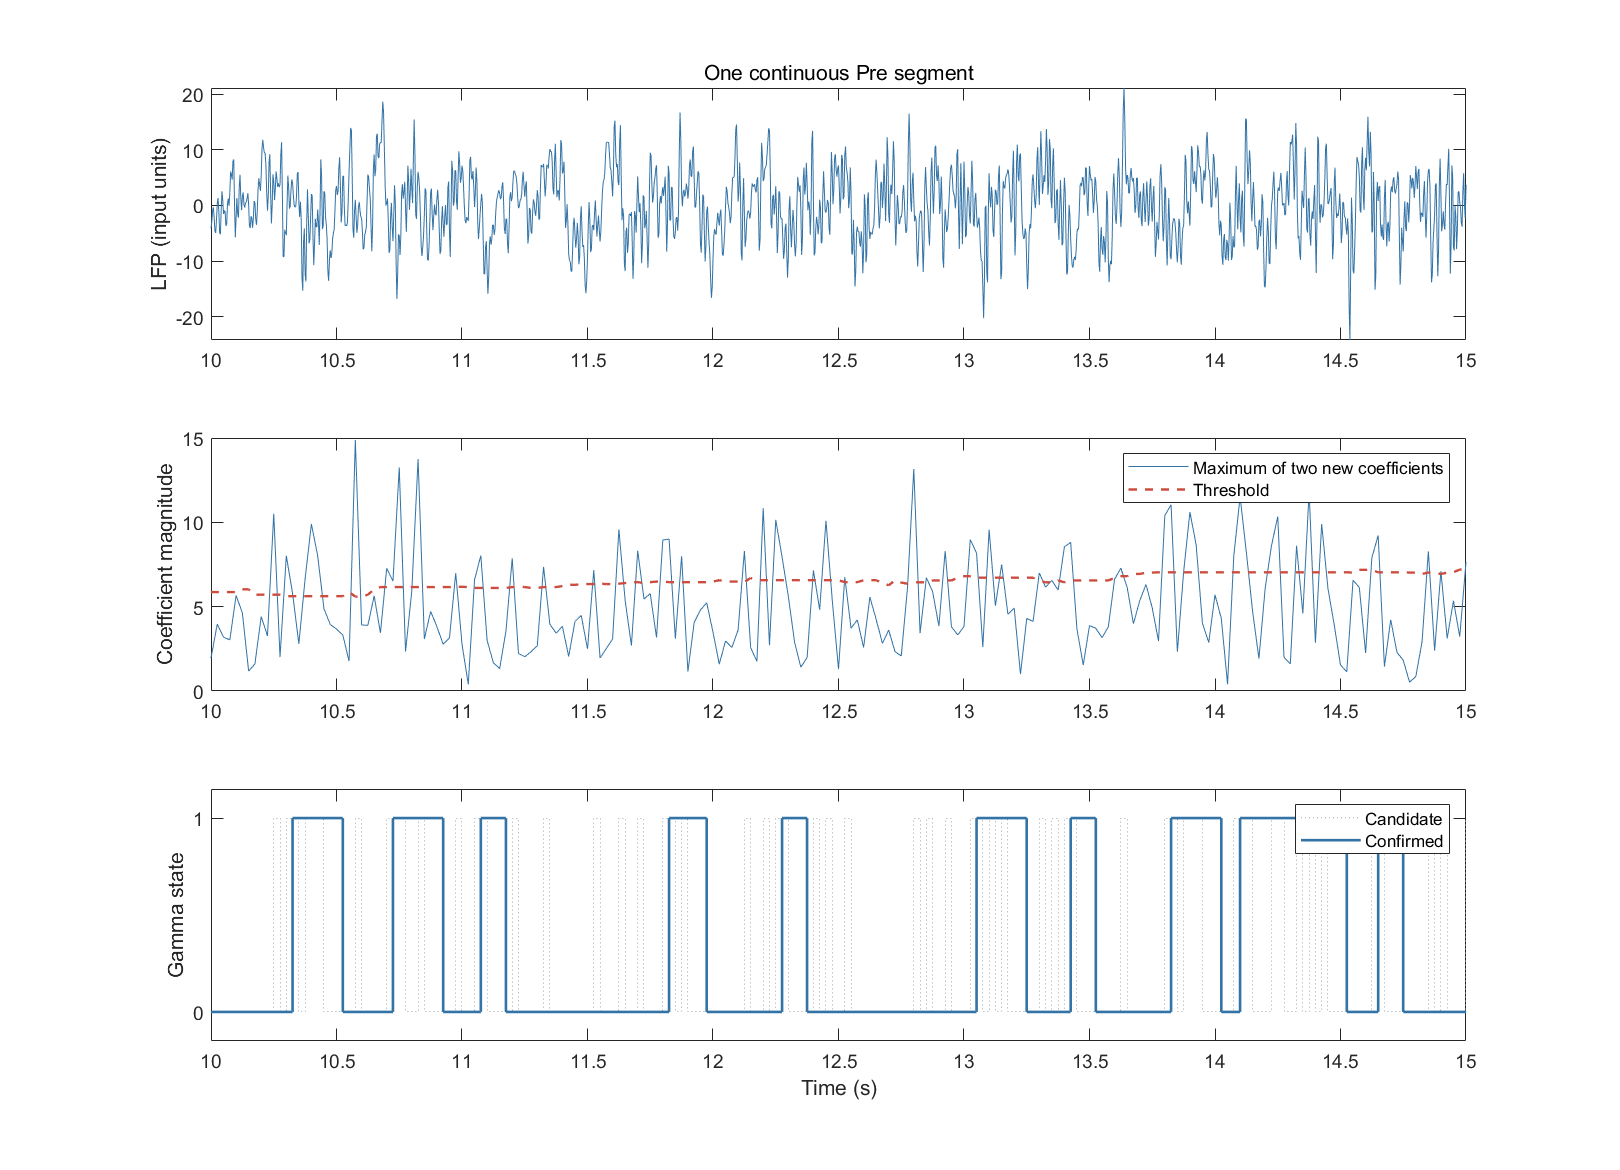

fig=figure('Color','w','Position',[100 100 1080 780]);
subplot(3,1,1); plot((0:numel(signal)-1)/fs,signal,'Color',[0.2 0.45 0.65]);
xlim(previewSeconds); ylabel('LFP (input units)'); title('One continuous Pre segment');
subplot(3,1,2); plot(time_s,max(abs(coefficients),[],2),'Color',[0.2 0.45 0.65]); hold on;
plot(time_s,threshold,'--','Color',[0.8 0.3 0.25],'LineWidth',1.2);
xlim(previewSeconds); ylabel('Coefficient magnitude'); legend('Maximum of two new coefficients','Threshold');
subplot(3,1,3); stairs(time_s,candidate,':','Color',[0.65 0.65 0.65]); hold on;
stairs(time_s,state,'Color',[0.2 0.45 0.65],'LineWidth',1.3);
xlim(previewSeconds); ylim([-0.15 1.15]); yticks([0 1]);
xlabel('Time (s)'); ylabel('Gamma state'); legend('Candidate','Confirmed');
exportgraphics(fig,fullfile(outDir,'state_detection_example.png'),'Resolution',180);

## 6. Save states AND their time base

state_fs is 40 updates/s, not the LFP sampling rate of 320 samples/s.

settings=struct('fs',fs,'original_fs',originalFs,'window_samples',windowSamples, ...
    'update_samples',updateSamples,'basis',waveletBasis,'node',targetNode, ...
    'initialization_updates',nInit,'n1',extraGamma1,'n2',extraGamma0, ...
    'coefficient_fraction',coefficientFraction,'reference_update',referenceMode, ...
    'extension_mode','sym','example_only',true);
save(fullfile(outDir,'gamma_states_example.mat'),'state','candidate','threshold', ...
    'coefficients','time_s','state_fs','valid','settings');
fprintf('Valid duration: %.3f s; gamma1 coverage: %.2f%%.\n',sum(valid)/state_fs,100*mean(state(valid)));

Valid duration: 57.000 s; gamma1 coverage: 27.02%.


% Step 08 summarizes this example only. It does not change paper state results.